rng('default');

% RF parameters
fc = 38e9;                                       % Carrier frequency (Hz)
c = physconst('LightSpeed');                     % Speed of propagation (m/s)
bw = 1e9;                                      % Bandwidth (Hz)
sampleRate = bw;                                 % Sample rate (Hz)

Pt = 50;                                         % Peak power (W) 
Pr = 10;
Gtx = 20;                                        % Tx antenna gain (dB)
Grx = 20;                                        % Rx antenna gain (dB) 
NF = 2.9;                                        % Noise figure (dB) 

% Transceiver components
antenna = phased.IsotropicAntennaElement('BackBaffled',false);
transmitter = phased.Transmitter('Gain',Gtx,'PeakPower',Pt);
radiator = phased.Radiator('Sensor',antenna,'OperatingFrequency',fc);
collector = phased.Collector('Sensor',antenna,'OperatingFrequency',fc);
receiver = phased.Receiver('AddInputNoise',true,'Gain',Grx,...
         'NoiseFigure',NF,'SampleRate',sampleRate);

channel = phased.FreeSpace('PropagationSpeed',c,'OperatingFrequency',fc,...
   'SampleRate',sampleRate,'TwoWayPropagation',false);

% Device platform
tgtpos = [9; 4; 0];                              % Device position (m)
tgtvel = [0; 0; 0];                              % Device velocity (m/s)
tgtplatform = phased.Platform('InitialPosition',tgtpos,'Velocity',tgtvel); 

% Anchor platform
anchorpos = [5 11 15 7 10 3;...
            5 2 9 1 6 4;...
            0 0 0 0 0 0];                      % Anchor positions (m)
numAnchor = size(anchorpos,2);                   % Number of anchors 
anchorvel = zeros(3,numAnchor);                  % Anchor velocities (m/s)
anchorplatform = phased.Platform('InitialPosition',anchorpos,'Velocity',anchorvel);

% Configure OFDM waveform
N = 1024;                                        % Number of subbands (OFDM data carriers)
M = 1;                                           % Number of channel samples (OFDM symbols)
freqSpacing = bw/N;                              % Frequency spacing (Hz)
tsym = 1/freqSpacing;                            % OFDM symbol duration  (s)
maxDelay = 200e-9;                               % Maximum delay (s)
rmax = maxDelay*c;                               % Maximum range of interest (m)
tcp = range2time(rmax);                          % Duration of the CP (s)
Ncp = ceil(sampleRate*tcp);                      % Length of the CP in subcarriers
tcp = Ncp/sampleRate;                            % Adjusted duration of the CP (s)
tWave = tsym + tcp;                              % OFDM symbol duration with CP (s)
Ns = N + Ncp;                                    % Number of subcarriers in one OFDM symbol

% Estimated channel
X = cell(1,numAnchor);
ranges = zeros(1, numAnchor);
estimated_ranges_ToA = zeros(1, numAnchor);
n = 2 %Freespace pathloss model

n = 2

  -14.0362
         0



rxrange = 4.1231

rxang =   165.9638
         0


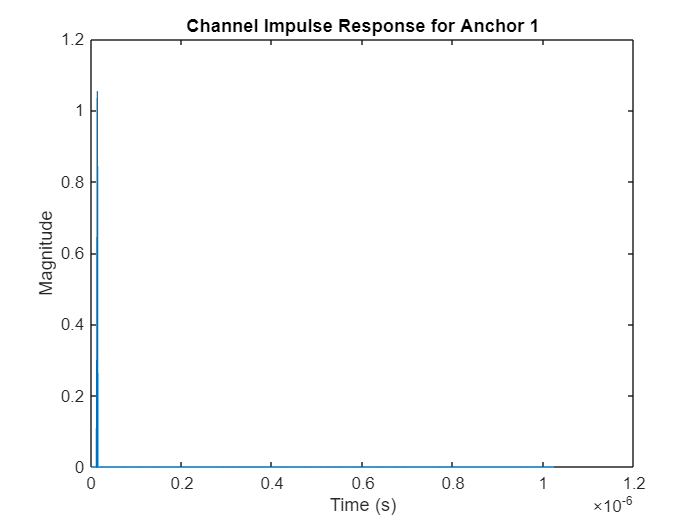

Estimated Range using ToA for Anchor 1: 4.1971 meters


   135
     0



rxrange = 2.8284

rxang =    -45
     0


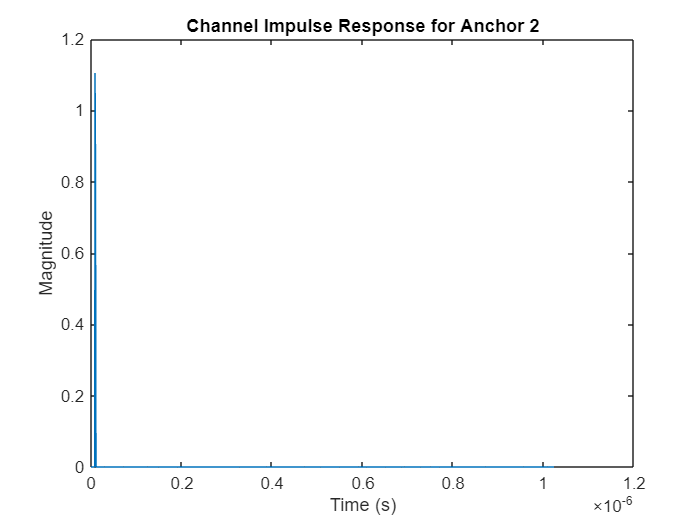

Estimated Range using ToA for Anchor 2: 2.6981 meters


 -140.1944
         0



rxrange = 7.8102

rxang =    39.8056
         0


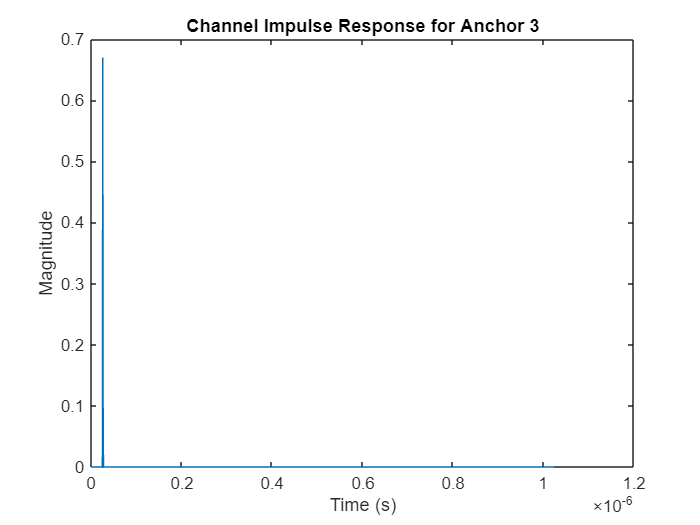

Estimated Range using ToA for Anchor 3: 7.7946 meters


   56.3099
         0



rxrange = 3.6056

rxang =  -123.6901
         0


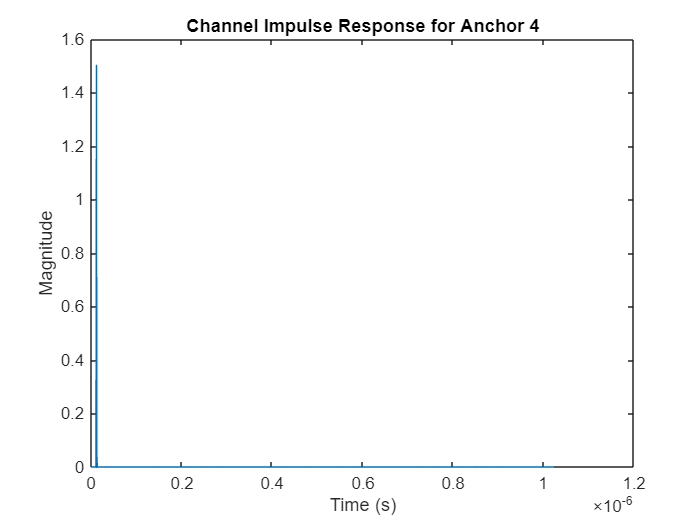

Estimated Range using ToA for Anchor 4: 3.5975 meters


 -116.5651
         0



rxrange = 2.2361

rxang =    63.4349
         0


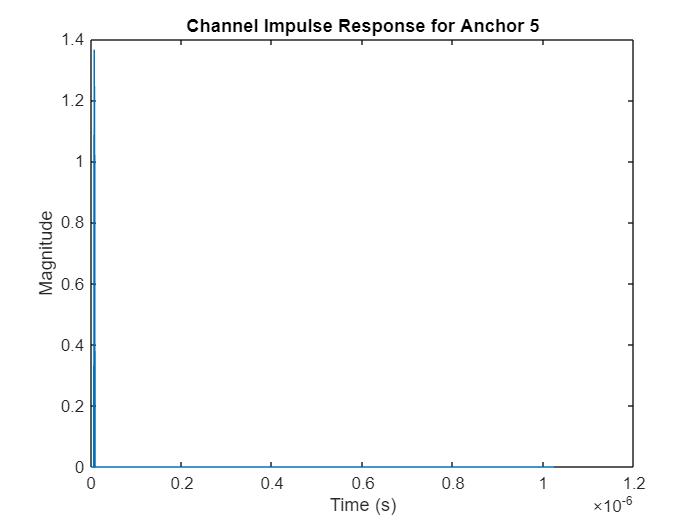

Estimated Range using ToA for Anchor 5: 2.0985 meters


     0
     0



rxrange = 6

rxang =    180
     0


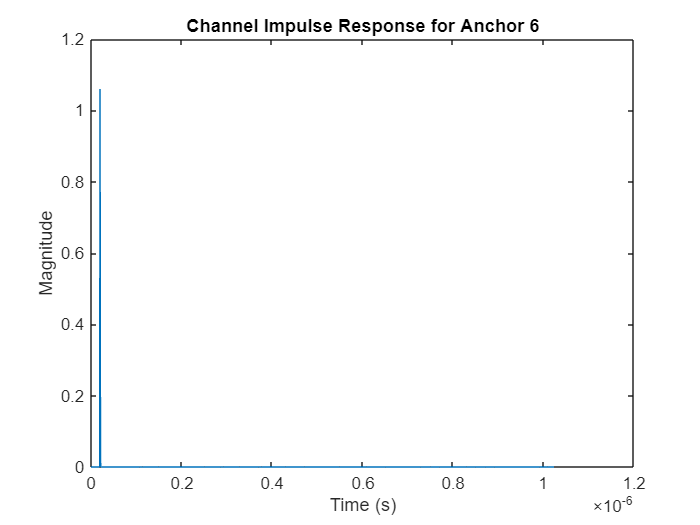

Estimated Range using ToA for Anchor 6: 5.9958 meters



% OFDM waveform propagation and channel estimation
for idxAnchor = 1:numAnchor

    % Modulate OFDM waveform with BPSK modulation on each data carrier
    bpskSymbol = randi([0,1],[N M])*2-1;             % BPSK symbol on each data carrier
    sigmod = ifft(ifftshift(bpskSymbol,1),[],1);     % OFDM symbols
    sig = sigmod([end-Ncp+(1:Ncp),1:end],:);         % OFDM symbols with cyclic prefix
    sig = sig/max(abs(sig),[],'all');                % Power-normalized OFDM signal

    % Initialize estimated channel
    x = complex(zeros(size(sig)));

    % Transceiver chain
    for m = 1:M
        % Update radar and device positions
        [tx_pos,tx_vel] = anchorplatform(tWave);
        [rx_pos,rx_vel] = tgtplatform(tWave);

        % Calculate the transmit angle
        [~,txang] = rangeangle(rx_pos,tx_pos(:,idxAnchor)); 
        disp(txang);

        % Transmitted signal
        txsig = transmitter(sig);

        % Radiate signal towards the receiver 
        radtxsig = radiator(txsig(:,m),txang); 

        % Propagate the signal
        chansig = channel(radtxsig,tx_pos(:,idxAnchor),rx_pos,...
            tx_vel(:,idxAnchor),rx_vel);

        % Calculate the receive angle
        [rxrange,rxang] = rangeangle(tx_pos(:,idxAnchor),rx_pos);
        rxrange
        rxang

        ranges(idxAnchor) = rxrange;

        % Collect signal at the receive antenna
        rxsig = collector(chansig,rxang);

        % Receive signal at the receiver
        x(:,m) = receiver(rxsig);

    end

    % Remove the cyclic prefix 
    xrmvcp = x((Ncp+1):(Ncp+N),:);

    % Demodulate the received OFDM signal
    xdemod = fftshift(fft(xrmvcp,[],1),1);

    % Remove BPSK symbol on each data carrier to estimate the channel frequency response
    H_f = xdemod ./ bpskSymbol;

    % Perform IFFT to get the channel impulse response
    h_t = ifft(H_f, [], 1);

    % Compute the magnitude of the impulse response
    h_t_mag = abs(h_t);

    % Plot the impulse response (optional)
    figure;
    plot((0:length(h_t_mag)-1)/sampleRate, h_t_mag);
    xlabel('Time (s)');
    ylabel('Magnitude');
    title(['Channel Impulse Response for Anchor ', num2str(idxAnchor)]);

    % Find the index of the first significant peak
    [~, idx_peak] = max(h_t_mag);

    % Convert index to time delay
    time_delay = (idx_peak - 1) / sampleRate;  % Time delay in seconds

    % Calculate the estimated range
    estimatedRange_ToA = time_delay * c;  % Range in meters

    % Display the estimated range
    disp(['Estimated Range using ToA for Anchor ', num2str(idxAnchor), ': ', num2str(estimatedRange_ToA), ' meters']);

    % Store the estimated range
    estimated_ranges_ToA(idxAnchor) = estimatedRange_ToA;

    % Remove BPSK symbol on each data carrier
    X{idxAnchor} = xdemod./bpskSymbol;

    % Reset platforms for the next anchor
    reset(anchorplatform);
    reset(tgtplatform);
end

ranges

ranges =     4.1231    2.8284    7.8102    3.6056    2.2361    6.0000


estimated_ranges_ToA

estimated_ranges_ToA =     4.1971    2.6981    7.7946    3.5975    2.0985    5.9958


tgtpos2D = tgtpos(1:2,:)

tgtpos2D =      9
     4


anchorPositions2D = anchorpos(1:2,:)

anchorPositions2D =      5    11    15     7    10     3
     5     2     9     1     6     4


% pos estimation usign LS
estimated_ranges = estimated_ranges_ToA;
anchor_positions = anchorPositions2D;

numAnchors = size(anchor_positions, 2);

A = zeros(numAnchors - 1, 2);
b = zeros(numAnchors - 1, 1);

refAnchorPos = anchor_positions(:, 1);
refRange = estimated_ranges(1);

for i = 2:numAnchors
    xi = anchor_positions(1, i);
    yi = anchor_positions(2, i);
    ri = estimated_ranges(i);
    
    A(i-1, :) = [2*(xi - refAnchorPos(1)), 2*(yi - refAnchorPos(2))];
    b(i-1) = (refRange^2 - ri^2) - (refAnchorPos(1)^2 - xi^2) - (refAnchorPos(2)^2 - yi^2);
end

initial_estimate = A\b

initial_estimate =     9.0756
    3.9315



disp('Initial position estimate using least squares:');

Initial position estimate using least squares:


disp(initial_estimate);

    9.0756
    3.9315



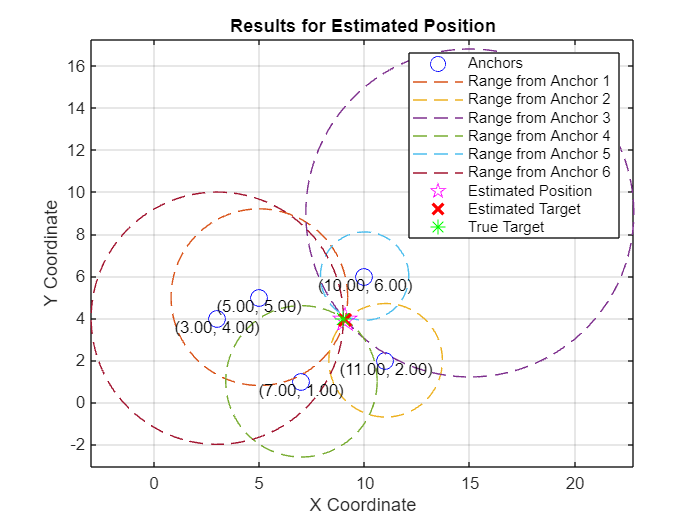


figure;
plot(anchorPositions2D(1, :), anchorPositions2D(2, :), 'bo', 'MarkerSize', 10, 'DisplayName', 'Anchors');
hold on;

theta = linspace(0, 2*pi, 100);
for i = 1:numAnchors
    xi = anchorPositions2D(1, i);
    yi = anchorPositions2D(2, i);
    ri = estimated_ranges(i);
    x_circle = xi + ri * cos(theta);
    y_circle = yi + ri * sin(theta);
    plot(x_circle, y_circle, '--', 'DisplayName', sprintf('Range from Anchor %d', i));
end

plot(initial_estimate(1), initial_estimate(2), 'p', 'Color', 'm', 'MarkerSize', 15, ...
    'DisplayName', 'Estimated Position');

plot(initial_estimate(1,:), initial_estimate(2,:), 'rx', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Estimated Target');

plot(tgtpos2D(1), tgtpos2D(2), 'g*', 'MarkerSize', 10, 'DisplayName', 'True Target');

for i = 1:numAnchors
    text(anchorPositions2D(1, i), anchorPositions2D(2, i), ...
        ['(' num2str(anchorPositions2D(1, i), '%.2f') ', ' num2str(anchorPositions2D(2, i), '%.2f') ')'], ...
        'VerticalAlignment', 'top', 'HorizontalAlignment', 'center');
end

legend show;
xlabel('X Coordinate');
ylabel('Y Coordinate');
title('Results for Estimated Position');
axis equal;
grid on;


diff = tgtpos2D - initial_estimate;
sqDiff = diff.^2;
meanSqDiff = mean(sqDiff);
rmse = sqrt(meanSqDiff);
disp("RMSE for estimated position: ");

RMSE for estimated position: 


disp(rmse);

    0.0722



%intersection area
%pairwise intersection
intersection_areas = zeros(numAnchors);
for i = 1:numAnchors
    for j = i+1:numAnchors
        r1 = estimated_ranges(i);
        r2 = estimated_ranges(j);
        d = norm(anchorpos(1:2, i) - anchorpos(1:2, j));
        
        intersection_areas(i, j) = calculateIntersectionArea(r1, r2, d);
    end
end

% Display pairwise intersection areas
for i = 1:numAnchors
    for j = i+1:numAnchors
        fprintf('Intersection area between Anchor %d and Anchor %d: %.2f m^2\n', i, j, intersection_areas(i, j));
    end
end

Intersection area between Anchor 1 and Anchor 2: 0.19 m^2
Intersection area between Anchor 1 and Anchor 3: 4.11 m^2
Intersection area between Anchor 1 and Anchor 4: 14.79 m^2
Intersection area between Anchor 1 and Anchor 5: 2.78 m^2
Intersection area between Anchor 1 and Anchor 6: 53.50 m^2
Intersection area between Anchor 2 and Anchor 3: 9.18 m^2
Intersection area between Anchor 2 and Anchor 4: 7.05 m^2
Intersection area between Anchor 2 and Anchor 5: 1.11 m^2
Intersection area between Anchor 2 and Anchor 6: 0.76 m^2
Intersection area between Anchor 3 and Anchor 4: 0.06 m^2
Intersection area between Anchor 3 and Anchor 5: 13.68 m^2
Intersection area between Anchor 3 and Anchor 6: 2.42 m^2
Intersection area between Anchor 4 and Anchor 5: 0.00 m^2
Intersection area between Anchor 4 and Anchor 6: 24.75 m^2
Intersection area between Anchor 5 and Anchor 6: 1.67 m^2



% Function to calculate intersection area between two circles
function A = calculateIntersectionArea(r1, r2, d)
    % r1, r2 are radii of circles
    % d is the distance between the circle centers
    if d >= (r1 + r2)
        % No intersection
        A = 0;
    elseif d <= abs(r1 - r2)
        % One circle is completely inside the other
        A = pi * min(r1, r2)^2;
    else
        % Partial overlap
        part1 = r1^2 * acos((d^2 + r1^2 - r2^2) / (2 * d * r1));
        part2 = r2^2 * acos((d^2 + r2^2 - r1^2) / (2 * d * r2));
        part3 = 0.5 * sqrt((-d + r1 + r2) * (d + r1 - r2) * (d - r1 + r2) * (d + r1 + r2));
        A = part1 + part2 - part3;
    end
end

x_min = min(anchorpos(1, :) - estimated_ranges);
x_max = max(anchorpos(1, :) + estimated_ranges);
y_min = min(anchorpos(2, :) - estimated_ranges);
y_max = max(anchorpos(2, :) + estimated_ranges);

grid_resolution = 0.1; 
[x_grid, y_grid] = meshgrid(x_min:grid_resolution:x_max, y_min:grid_resolution:y_max);

common_area_points = zeros(size(x_grid));

for i = 1:numAnchors
    xi = anchorpos(1, i);
    yi = anchorpos(2, i);
    ri = estimated_ranges(i);
    
    distances = sqrt((x_grid - xi).^2 + (y_grid - yi).^2);
    
    common_area_points = common_area_points + (distances <= ri);
end

common_area_points = (common_area_points == numAnchors);

plot(x_grid(common_area_points), y_grid(common_area_points), 'k.', 'MarkerSize', 1, 'DisplayName', 'Common Intersection Area');

area_per_point = grid_resolution^2;
common_intersection_area = sum(common_area_points(:)) * area_per_point;
fprintf('Common Intersection Area: %.2f m^2\n', common_intersection_area);

Common Intersection Area: 0.00 m^2


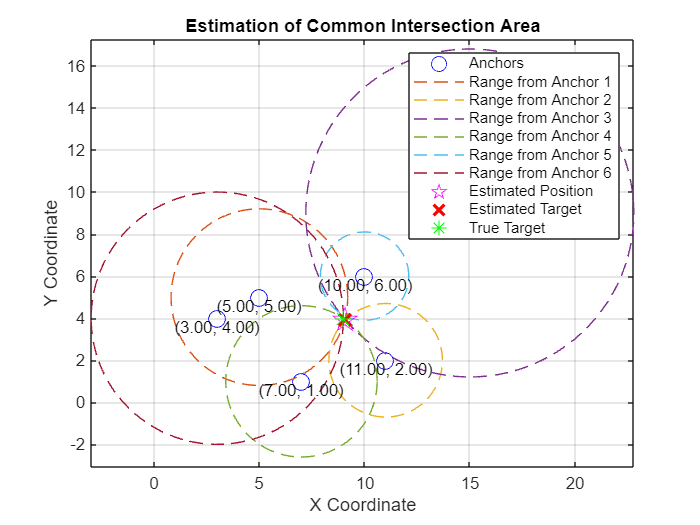


legend show;
xlabel('X Coordinate');
ylabel('Y Coordinate');
title('Estimation of Common Intersection Area');
axis equal;
grid on;


%legend show;
% 
% % Bounding box
% x_min = min(anchorpos(1, :) - estimated_ranges) - 1;
% x_max = max(anchorpos(1, :) + estimated_ranges) + 1;
% y_min = min(anchorpos(2, :) - estimated_ranges) - 1;
% y_max = max(anchorpos(2, :) + estimated_ranges) + 1;
% 
% % Number of random samples
% num_samples = 1e8;
% 
% % Generate random points
% x_rand = x_min + (x_max - x_min) * rand(1, num_samples);
% y_rand = y_min + (y_max - y_min) * rand(1, num_samples);
% 
% % Check if each point lies within all three circles
% inside_all_circles = true(1, num_samples);
% 
% for i = 1:numAnchors
%     xi = anchorpos(1, i);
%     yi = anchorpos(2, i);
%     ri = estimated_ranges(i);
% 
%     % Calculate the distance from each random point to the current anchor
%     
%     distances = sqrt((x_rand - xi).^2 + (y_rand - yi).^2);
% 
%     % Update points that lie within all circles
%     inside_all_circles = inside_all_circles & (distances <= ri);
% end
% 
% % Estimate the common intersection area
% area_bounding_box = (x_max - x_min) * (y_max - y_min);
% common_intersection_area = (sum(inside_all_circles) / num_samples) * area_bounding_box;
% 
% % Display the result
% fprintf('Common MC Intersection Area between all 3 circles: %.2f m^2\n', common_intersection_area);

% % Plotting for visualization
% plot(anchorpos(1, :), anchorpos(2, :), 'bo', 'MarkerSize', 10, 'DisplayName', 'Anchors');
% for i = 1:numAnchors
%     xi = anchorpos(1, i);
%     yi = anchorpos(2, i);
%     ri = estimated_ranges(i);
%     theta = linspace(0, 2*pi, 100);
%     x_circle = xi + ri * cos(theta);
%     y_circle = yi + ri * sin(theta);
%     plot(x_circle, y_circle, '--', 'DisplayName', sprintf('Range from Anchor %d', i));
% end
% 
% % Plot true target position (if known)
% plot(tgtpos(1), tgtpos(2), 'g*', 'MarkerSize', 10, 'DisplayName', 'True Target');
% 
% % Plot common area points for visualization
% plot(x_rand(inside_all_circles), y_rand(inside_all_circles), 'k.', 'MarkerSize', 1, 'DisplayName', 'Common Intersection Area');
% 
% legend show;
% xlabel('X Coordinate');
% ylabel('Y Coordinate');
% title('Monte Carlo Estimation of Common Intersection Area');
% axis equal;
% grid on;

%Recursive Least Squares
mu = initial_estimate;
observedRanges = estimated_ranges;
tolerance = 1e-5;
maxIters = 100;
resnorm_values = zeros(1, maxIters);

anchorPositions2D;

nAnchors = size(anchorPositions2D, 2);

rmse_values = zeros(1, maxIters);

for iteration = 1:maxIters
    measuredRanges = sqrt(sum((mu - anchorPositions2D).^2))
    r = observedRanges' - measuredRanges'; %residuals
    resnorm = sum(r.^2);

    resnorm_values(iteration) = resnorm;

    H = zeros(nAnchors, 2);
    for i = 1:nAnchors
        dx = mu(1) - anchorPositions2D(1, i);
        dy = mu(2) - anchorPositions2D(2, i);
        d_i0 = measuredRanges(i);
        H(i, :) = [dx / d_i0, dy / d_i0];
    end

    delta = (H' * H) \ (H' * r);
    mu = mu + delta
    norm_delta = norm(delta);

    % Calculate RMSE for refined position
    diff_rls = tgtpos2D - mu;
    sqDiff_rls = diff_rls.^2;
    meanSqDiff_rls = mean(sqDiff_rls);
    rmse_values(iteration) = sqrt(meanSqDiff_rls(:));
    disp(['RMSE at Iteration ', num2str(iteration), ': ', num2str(rmse_values(iteration))]);

    if norm_delta < tolerance
        disp(['Converged after ', num2str(iteration), ' iterations']);
        resnorm_values = resnorm_values(1:iteration);
        rmse_values = rmse_values(1:iteration);
        break;
    end
end

measuredRanges =     4.2134    2.7265    7.7967    3.5919    2.2657    6.0760


mu =     9.0648
    3.9916


RMSE at Iteration 1: 0.046232


measuredRanges =     4.1880    2.7769    7.7659    3.6350    2.2154    6.0648


mu =     9.0652
    3.9907


RMSE at Iteration 2: 0.046591


measuredRanges =     4.1886    2.7760    7.7662    3.6345    2.2161    6.0652


mu =     9.0652
    3.9907


RMSE at Iteration 3: 0.04658


measuredRanges =     4.1886    2.7760    7.7662    3.6345    2.2161    6.0652


mu =     9.0652
    3.9907


RMSE at Iteration 4: 0.046581


Converged after 4 iterations


rmse_values

rmse_values =     0.0462    0.0466    0.0466    0.0466



% Display refined position
disp('Refined target position after Recursive LS:');

Refined target position after Recursive LS:


disp(mu);

    9.0652
    3.9907



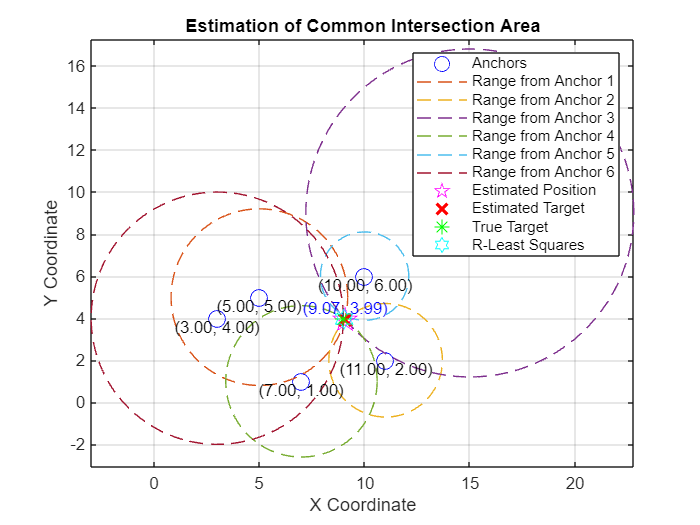


plot(mu(1), mu(2), 'h', 'Color', 'c', 'MarkerSize', 12, ...
    'DisplayName', 'R-Least Squares');

% Label the new position with coordinates
text(mu(1), mu(2), ...
    ['(' num2str(mu(1), '%.2f') ', ' num2str(mu(2), '%.2f') ')'], ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center', 'Color', 'blue');
hold off;

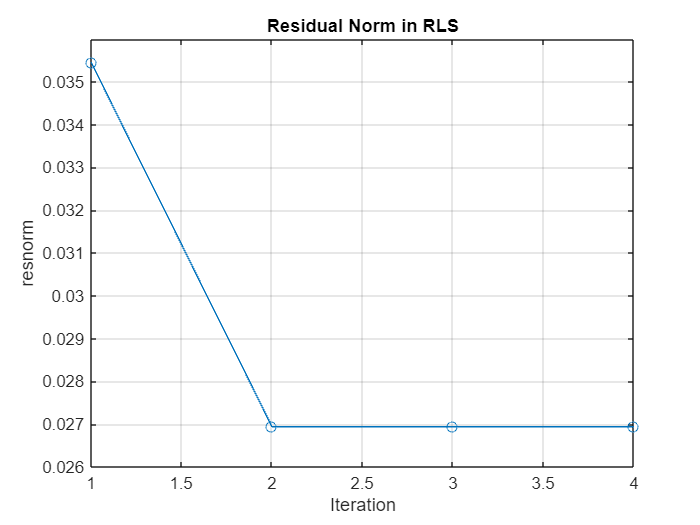


% resnorm values
figure;
plot(1:length(resnorm_values), resnorm_values, '-o');
xlabel('Iteration');
ylabel('resnorm');
title('Residual Norm in RLS');
grid on;

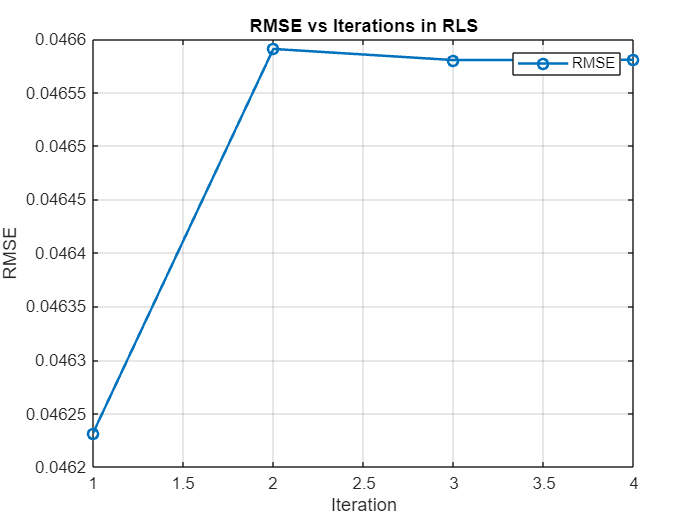


% rmse vs Iterations
figure;
plot(1:length(rmse_values), rmse_values, '-o', 'LineWidth', 1.5);
xlabel('Iteration');
ylabel('RMSE');
title('RMSE vs Iterations in RLS');
grid on;

legend('RMSE', 'Location', 'northeast');